clear
clearvars
syms theta_1 theta_2 theta_3 theta_4 P_x P_y P_z L_1 L_2 L_3 L_4 D_r D_z
assume(theta_1,'real')
assume(theta_2,'real')
assume(theta_3,'real')
assume(theta_4,'real')



DHsym=[0, L_1, 0, sym(pi)/2, 0, 0;
    0, 0, L_2, 0, 0, sym(pi)/2;
    0, 0, L_3,0, 0, -sym(pi)/2;
    0, 0, L_4, sym(pi)/2 , 0, 0];

Lisym(1)=Link(DHsym(2,:));
Lisym(2)=Link(DHsym(3,:));


Robot_1sym=SerialLink(Lisym,'name','Robot')

 
Robot_1sym = 
 
Robot (2 axis, RR, stdDH, fastRNE)                               
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|        L_2|          0|       pi/2|
|  2|         q2|          0|        L_3|          0|      -pi/2|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 




FKINE=simplify(Robot_1sym.A([1 2],[theta_2 theta_3]))

$$FKINE = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)-L_{2}\,\sin\left(\theta_{2}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

FKINE=FKINE(1:2,4)

$$FKINE = \left(\begin{array}{c} L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)-L_{2}\,\sin\left(\theta_{2}\right)\\ L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right) \end{array}\right)$$

[theta_2s,theta_3s]=solve(FKINE==[D_r;D_z],[theta_2,theta_3])

$$theta\_2s = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{2\,D_{r}\,L_{2}-2\,L_{2}\,L_{3}-\frac{{D_{r}}^{2}\,\sigma_{3}}{\sigma_{1}}-\frac{{D_{z}}^{2}\,\sigma_{3}}{\sigma_{1}}+\frac{{L_{2}}^{2}\,\sigma_{3}}{\sigma_{1}}+\frac{{L_{3}}^{2}\,\sigma_{3}}{\sigma_{1}}}{\sigma_{2}}\right)\\ -2\,\mathrm{atan}\left(\frac{2\,D_{r}\,L_{2}-2\,L_{2}\,L_{3}+\frac{{D_{r}}^{2}\,\sigma_{4}}{\sigma_{1}}+\frac{{D_{z}}^{2}\,\sigma_{4}}{\sigma_{1}}-\frac{{L_{2}}^{2}\,\sigma_{4}}{\sigma_{1}}-\frac{{L_{3}}^{2}\,\sigma_{4}}{\sigma_{1}}}{\sigma_{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}-{L_{3}}^{2}\\ \sigma_{2}={D_{r}}^{2}+{D_{z}}^{2}+2\,D_{z}\,L_{2}+{L_{2}}^{2}-{L_{3}}^{2}\\ \sigma_{3}=\sigma_{5}-2\,L_{2}\,L_{3}\\ \sigma_{4}=\sigma_{5}+2\,L_{2}\,L_{3}\\ \sigma_{5}=\sqrt{\left(-{D_{r}}^{2}-{D_{z}}^{2}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}\right)\,\left({D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}\right)} \end{array}$$

$$theta\_3s = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sigma_{1}-2\,L_{2}\,L_{3}}{{D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}-{L_{3}}^{2}}\right)\\ 2\,\mathrm{atan}\left(\frac{\sigma_{1}+2\,L_{2}\,L_{3}}{{D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}-{L_{3}}^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(-{D_{r}}^{2}-{D_{z}}^{2}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}\right)\,\left({D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}\right)} \end{array}$$


theta_2s1=simplify(theta_2s(1))

$$theta\_2s1 = -2\,\mathrm{atan}\left(\frac{2\,D_{r}\,L_{2}-\sqrt{-{D_{r}}^{4}-2\,{D_{r}}^{2}\,{D_{z}}^{2}+2\,{D_{r}}^{2}\,{L_{2}}^{2}+2\,{D_{r}}^{2}\,{L_{3}}^{2}-{D_{z}}^{4}+2\,{D_{z}}^{2}\,{L_{2}}^{2}+2\,{D_{z}}^{2}\,{L_{3}}^{2}-{L_{2}}^{4}+2\,{L_{2}}^{2}\,{L_{3}}^{2}-{L_{3}}^{4}}}{{D_{r}}^{2}+{D_{z}}^{2}+2\,D_{z}\,L_{2}+{L_{2}}^{2}-{L_{3}}^{2}}\right)$$

theta_2s2=simplify(theta_2s(2))

$$theta\_2s2 = -2\,\mathrm{atan}\left(\frac{2\,D_{r}\,L_{2}+\sqrt{-{D_{r}}^{4}-2\,{D_{r}}^{2}\,{D_{z}}^{2}+2\,{D_{r}}^{2}\,{L_{2}}^{2}+2\,{D_{r}}^{2}\,{L_{3}}^{2}-{D_{z}}^{4}+2\,{D_{z}}^{2}\,{L_{2}}^{2}+2\,{D_{z}}^{2}\,{L_{3}}^{2}-{L_{2}}^{4}+2\,{L_{2}}^{2}\,{L_{3}}^{2}-{L_{3}}^{4}}}{{D_{r}}^{2}+{D_{z}}^{2}+2\,D_{z}\,L_{2}+{L_{2}}^{2}-{L_{3}}^{2}}\right)$$



theta_3s1=simplify(theta_3s(1))

$$theta\_3s1 = -2\,\mathrm{atan}\left(\frac{\sqrt{\left(-{D_{r}}^{2}-{D_{z}}^{2}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}\right)\,\left({D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}\right)}-2\,L_{2}\,L_{3}}{{D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}-{L_{3}}^{2}}\right)$$

theta_3s2=simplify(theta_3s(2))

$$theta\_3s2 = 2\,\mathrm{atan}\left(\frac{\sqrt{\left(-{D_{r}}^{2}-{D_{z}}^{2}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}\right)\,\left({D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}\right)}+2\,L_{2}\,L_{3}}{{D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}-{L_{3}}^{2}}\right)$$

clear
clearAllMemoizedCaches


L_1=0.137;
L_2=0.105;
L_3=0.105;
L_4=0.095;


L=[L_1 L_2 L_3 L_4]

L =     0.1370    0.1050    0.1050    0.0950


DH=[0, L(1), 0, (pi/2), 0, 0;
    0, 0, (L(2)), 0, 0, pi/2;
    0, 0, (L(3)),0, 0, -pi/2;
    0, 0, L(4), pi/2 , 0, 0];

Li(1)=Link(DH(1,:));
Li(2)=Link(DH(2,:));
Li(3)=Link(DH(3,:));
Li(4)=Link(DH(4,:));

Robot_1=SerialLink(Li,'name','Robot');
%Robot_q_1.tool = [1 0 0 L(4); 0 0 -1 0; 0 1 0 0; 0 0 0 1];
%A=simplify(Robot_q_1.A([1 2 3 4],[theta_1 theta_2 theta_3 theta_4]),"Steps",200)




q_1=[0.7853981633974483;
0.6530481254872835;
-1.7459907305629048;
1.6165413806739202]';
q_1=[0 60-150 130-60 170-150]*pi/180

q_1 =          0   -1.5708    1.2217    0.3491




q_1=[0 0 0 0]*pi/180

q_1 =      0     0     0     0


Robot_1.plot(q_1,'view',[155 15],'workspace',[-0.05 0.3 -0.3 0.3 -0.05 0.4],'joints','jointdiam',0.1);
p=Robot_1.fkine(q_1)

p =     1.0000         0         0    0.2000
         0   -1.0000   -0.0000    0.0000
         0    0.0000   -1.0000    0.2420
         0         0         0    1.0000


p=p(1:3,4)

p =     0.2000
    0.0000
    0.2420



P_x=0.2

P_x = 0.2000

P_y=0

P_y = 0

P_z=0.242

P_z = 0.2420

beta=0

beta = 0


qikine=ikine4r(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)

qikine = 	1.0e+-15 *

         0   -0.1573         0    0.1573


Robot_1.fkine(qikine)

ans =     1.0000    0.0000   -0.0000    0.2000
   -0.0000   -1.0000   -0.0000    0.0000
   -0.0000    0.0000   -1.0000    0.2420
         0         0         0    1.0000


Robot_1.animate(qikine)



Casos

Maximo

Home=[150 150 60 150]

Home =    150   150    60   150




q_1=([150 59.47 130.66 170.51]-Home)*pi/180

q_1 =          0   -1.5800    1.2332    0.3580


Robot_1.fkine(q_1)

ans =     0.9999   -0.0000    0.0112    0.2987
    0.0000   -1.0000   -0.0000   -0.0000
    0.0112    0.0000   -0.9999    0.1014
         0         0         0    1.0000


Robot_1.animate(q_1)
qikine=ikine4r(0.3,0,0.095,0,L_1,L_2,L_3,L_4)

qikine =          0   -1.6888    1.4026    0.2862


Robot_1.fkine(qikine)

ans =     1.0000   -0.0000    0.0000    0.3000
    0.0000   -1.0000   -0.0000   -0.0000
    0.0000    0.0000   -1.0000    0.0950
         0         0         0    1.0000


Robot_1.animate(qikine)

Minimo


q_2=([150 92.58 19 251.37]-Home)*pi/180

q_2 =          0   -1.0022   -0.7156    1.7692



Robot_1.fkine(q_2)

ans =     0.9987   -0.0000    0.0515    0.1680
    0.0000   -1.0000   -0.0000   -0.0000
    0.0515    0.0000   -0.9987    0.0946
         0         0         0    1.0000


Robot_1.animate(q_2)
qikine=ikine4r(0.168,0,0.095,0,L_1,L_2,L_3,L_4)

qikine =          0   -0.9348   -0.7455    1.6802


Robot_1.fkine(qikine)

ans =     1.0000   -0.0000    0.0000    0.1680
    0.0000   -1.0000   -0.0000   -0.0000
    0.0000    0.0000   -1.0000    0.0950
         0         0         0    1.0000


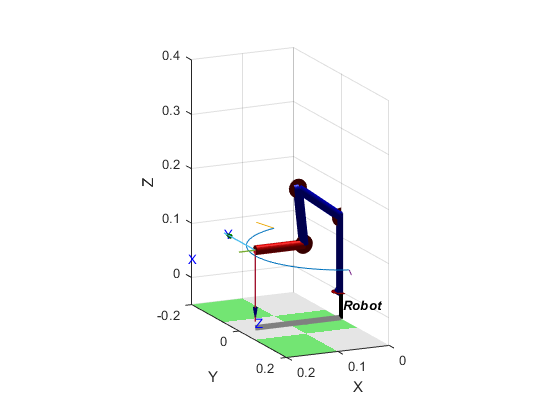

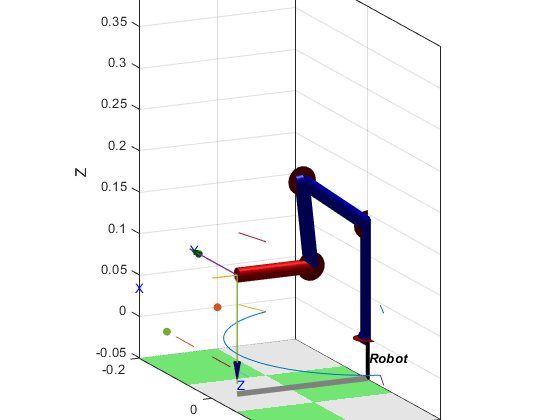

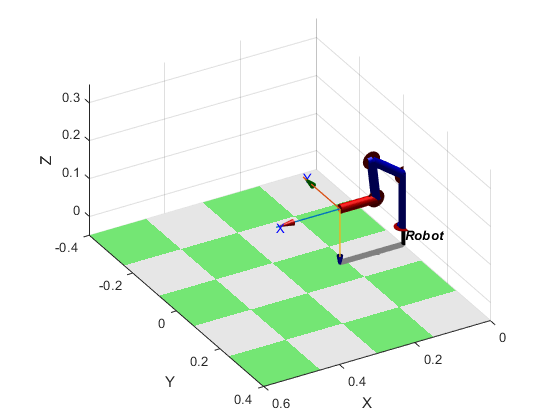

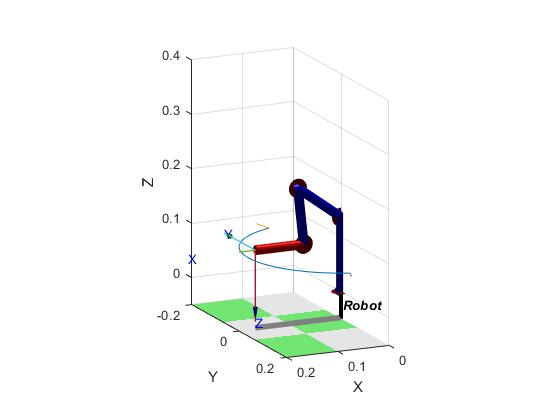

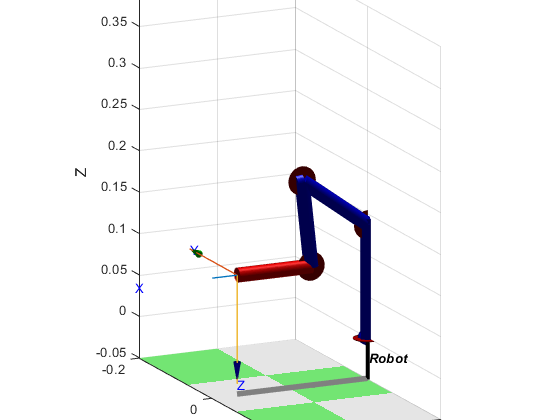

Robot_1.animate(qikine)

Portaherramientas

q_3=([86.72 91.99 49.51 222.66]-Home)*pi/180

q_3 =    -1.1044   -1.0125   -0.1831    1.2682


Robot_1.fkine(q_3)

ans =     0.4484   -0.8932    0.0326    0.0999
   -0.8909   -0.4496   -0.0648   -0.1986
    0.0725    0.0000   -0.9974    0.1018
         0         0         0    1.0000


Robot_1.animate(q_3)
qikine=ikine4r(0.1,-0.2,0.1018,0,L_1,L_2,L_3,L_4)

qikine =    -1.1071   -0.9551   -0.1949    1.1500


Robot_1.fkine(qikine)

ans =     0.4472   -0.8944   -0.0000    0.1000
   -0.8944   -0.4472    0.0000   -0.2000
   -0.0000    0.0000   -1.0000    0.1018
         0         0         0    1.0000


Robot_1.animate(qikine)

Portaherramientas2:


q_4=([95.84 92.92 48.34 222.36]-Home)*pi/180

q_4 =    -0.9453   -0.9962   -0.2035    1.2629




Robot_1.fkine(q_4)

ans =     0.5844   -0.8107    0.0370    0.1294
   -0.8090   -0.5855   -0.0512   -0.1792
    0.0631    0.0000   -0.9980    0.1022
         0         0         0    1.0000


Robot_1.animate(q_4)
qikine=ikine4r(0.129,-0.179,0.1022,0,L_1,L_2,L_3,L_4)

qikine =    -0.9463   -0.9400   -0.2312    1.1712


Robot_1.fkine(qikine)

ans =     0.5847   -0.8113   -0.0000    0.1290
   -0.8113   -0.5847   -0.0000   -0.1790
    0.0000    0.0000   -1.0000    0.1022
         0         0         0    1.0000


Robot_1.animate(qikine)

Portaherramientas 3

q_5=([148.24 99.32 31.64 226.76]-Home)*pi/180

q_5 =    -0.0307   -0.8845   -0.4950    1.3397


Robot_1.fkine(q_5)

ans =     0.9987   -0.0307   -0.0398    0.1960
   -0.0307   -0.9995    0.0012   -0.0060
   -0.0398    0.0000   -0.9992    0.0967
         0         0         0    1.0000


Robot_1.animate(q_5)
qikine=ikine4r(0.196,0,0.0967,0,L_1,L_2,L_3,L_4)

qikine =          0   -0.9240   -0.4822    1.4061


Robot_1.fkine(qikine)

ans =     1.0000   -0.0000    0.0000    0.1960
    0.0000   -1.0000   -0.0000   -0.0000
    0.0000    0.0000   -1.0000    0.0967
         0         0         0    1.0000


Robot_1.animate(qikine)

Punto de dibujo

q_6=([187.5 92.3 48.63 218.55]-Home)*pi/180

q_6 =     0.6545   -1.0071   -0.1984    1.1964


Robot_1.fkine(q_6)

ans =     0.7933    0.6088   -0.0072    0.1755
    0.6087   -0.7934   -0.0055    0.1347
   -0.0091    0.0000   -1.0000    0.0942
         0         0         0    1.0000


Robot_1.animate(q_6)
qikine=ikine4r(0.1755,0.1347,0.0942,0,L_1,L_2,L_3,L_4)

qikine =     0.6546   -1.0145   -0.1955    1.2100


Robot_1.fkine(qikine)

ans =     0.7933    0.6089    0.0000    0.1755
    0.6089   -0.7933   -0.0000    0.1347
    0.0000    0.0000   -1.0000    0.0942
         0         0         0    1.0000


Robot_1.animate(qikine)

Punto de dibujo 2

q_7=([80.57 90.82 52.44 217.09]-Home)*pi/180

q_7 =    -1.2118   -1.0329   -0.1319    1.1709


Robot_1.fkine(q_7)

ans =     0.3513   -0.9362    0.0021    0.0796
   -0.9362   -0.3514   -0.0057   -0.2122
    0.0061    0.0000   -1.0000    0.0949
         0         0         0    1.0000


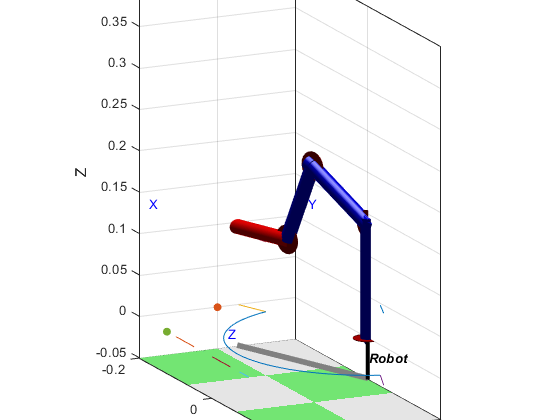

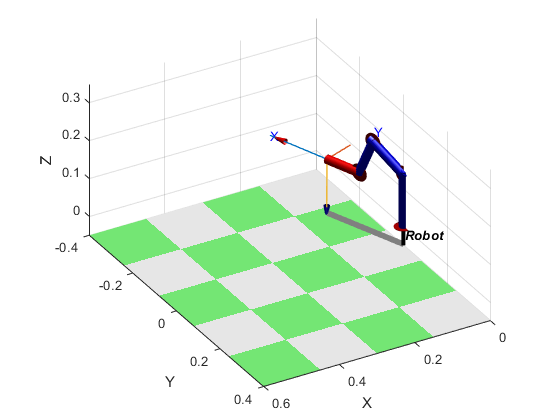

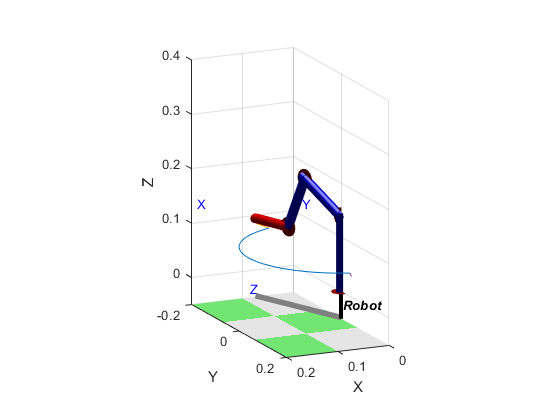

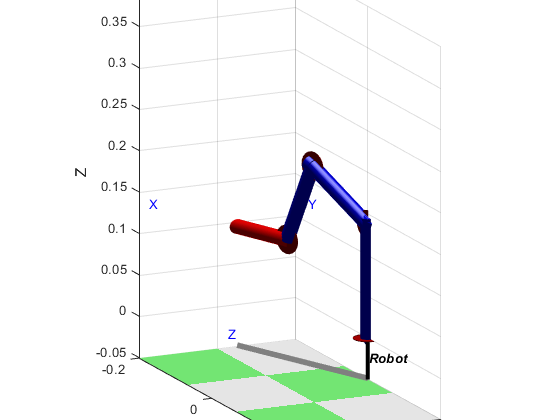

Robot_1.animate(q_7)

q_2=[0 95-150 25-60 240-150]*pi/180;

figure()

Robot_1.animate(q_2)

Robot_1.fkine(q_2)

q_3=[86.72-150 91.99-150 49.51-60 222.66-150]*pi/180

Robot_1.animate(q_3)

Robot_1.fkine(q_3)

q_4=[187.5-150 92.3-150 48.63-60 218.55-150]*pi/180

Robot_1.animate(q_4)

Robot_1.fkine(q_4)

q_5=[148.24-150 99.32-150 31.64-60 226.76-150]*pi/180

Robot_1.animate(q_5)

Robot_1.fkine(q_5)


N=200

N = 200

lim=70

lim = 70


tArr=linspace(0,5,N);
[s,sd,sdd] = lspb(-lim*pi/180, lim*pi/180, tArr);
sInt=int16(interp1([-150*pi/180 150*pi/180],[0 1023],s))

sInt = 200×1 int16 column vector
   273
   273
   273
   273
   273
   273
   274
   274
   275
   275


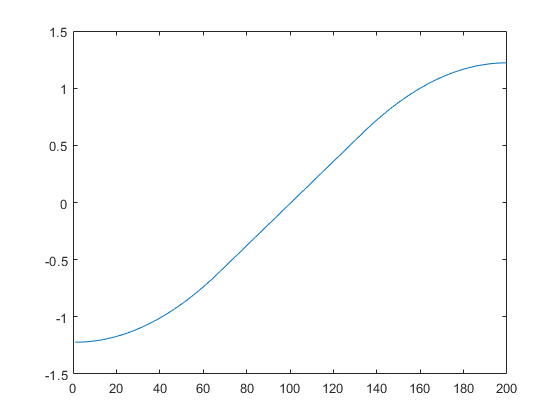


figure()
plot(s)


[-lim*pi/180 q_2(2:4)]

ans =    -1.2217   -1.0022   -0.7156    1.7692


[-lim*pi/180 q_1(2:4)]

ans =    -1.2217   -1.5800    1.2332    0.3580




for i=1:200
    Pmin=Robot_1.fkine([[s(i) q_2(2:4)]]);
    Pmax=Robot_1.fkine([[s(i) q_1(2:4)]]);
    LimMin(i,:)=Pmin(1:3,4)';
    LimMax(i,:)=Pmax(1:3,4)';
end
clf

figure()

plot3(LimMin(:,1),LimMin(:,2),LimMin(:,3)-10)

hold on

plot3(LimMax(:,1),LimMax(:,2),LimMax(:,3)-10)

plot3([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)],[LimMax(1,3) LimMin(1,3)]-10)

plot3([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)],[LimMax(end,3) LimMin(end,3)]-10)

hold off

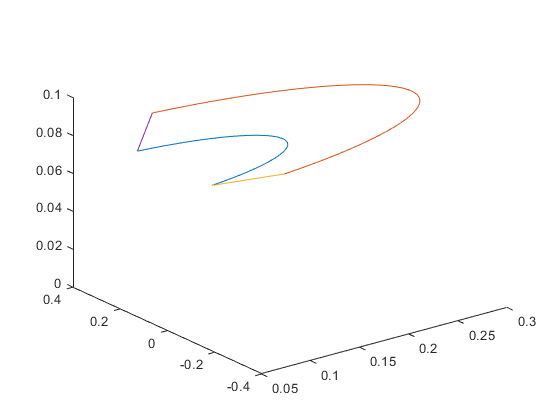

figure()
plot3(LimMin(:,1),LimMin(:,2),LimMin(:,3)-0.01)
hold on
plot3(LimMax(:,1),LimMax(:,2),LimMax(:,3)-0.01)
plot3([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)],[LimMax(1,3) LimMin(1,3)]-0.01)
plot3([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)],[LimMax(end,3) LimMin(end,3)]-0.01)
zlim([0 0.1])
hold off

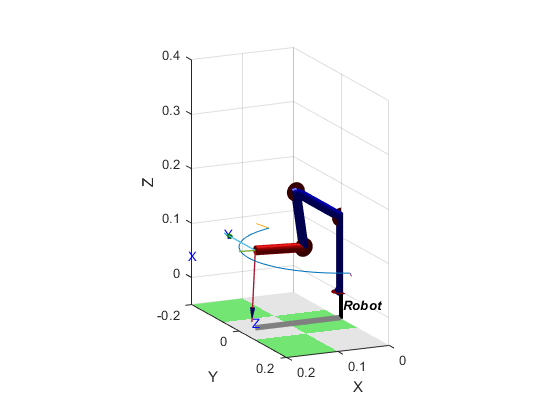

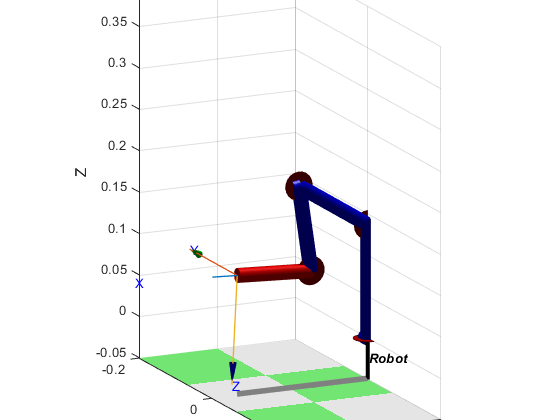


Robot_1.plot(q_2,'view',[150 30],'workspace',[-0.05 0.5 -0.4 0.4 -0.05 0.4],'joints','jointdiam',0.1);

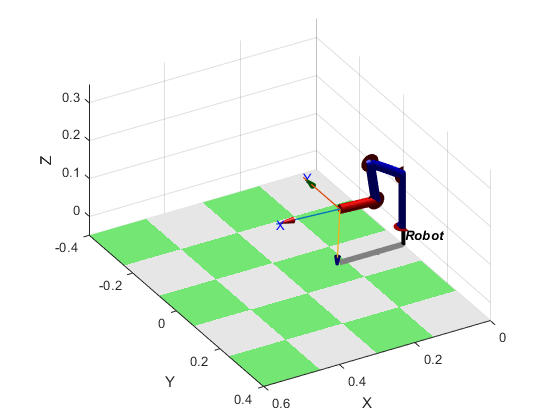

zlim([-0.05 0.35])

figure()
Robot_1.animate(q_1)
Robot_1.fkine(q_1)

ans =     0.9999   -0.0000    0.0112    0.2987
    0.0000   -1.0000   -0.0000   -0.0000
    0.0112    0.0000   -0.9999    0.1014
         0         0         0    1.0000


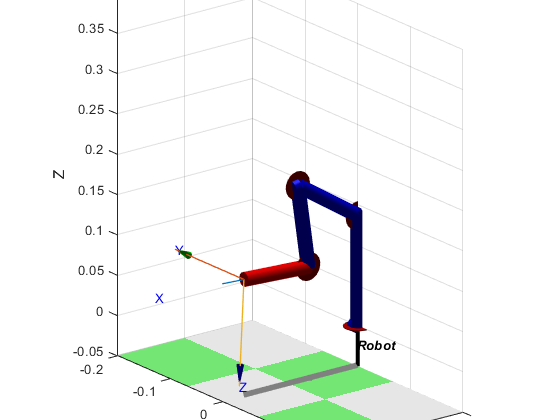

pause(1)
Robot_1.animate(q_2)

Robot_1.fkine(q_2)

ans =     0.9987   -0.0000    0.0515    0.1680
    0.0000   -1.0000   -0.0000   -0.0000
    0.0515    0.0000   -0.9987    0.0946
         0         0         0    1.0000



q2=interp1([0 1023],[-150*pi/180 150*pi/180],713)-150*pi/180

q2 = -1.5867

q3=interp1([0 1023],[-240*pi/180 60*pi/180],962)-60*pi/180

q3 = -0.3122

q4=interp1([0 1023],[-150*pi/180 150*pi/180],162)-150*pi/180

q4 = -4.4068


q=[0 q2 q3 q4]

q =          0   -1.5867   -0.3122   -4.4068


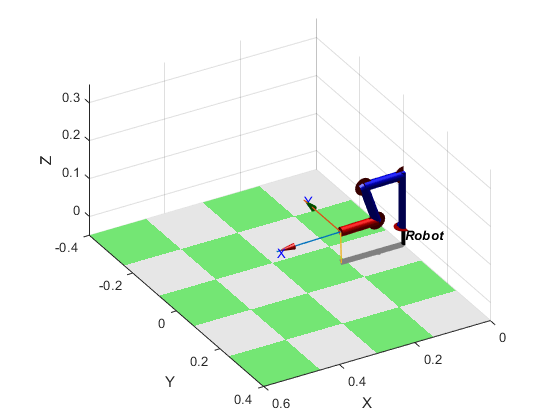

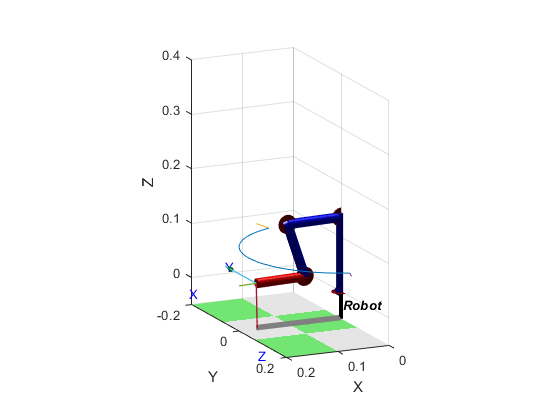

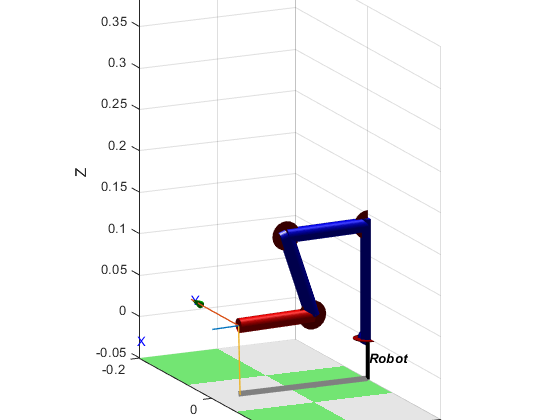

Robot_1.plot(q,'view',[150 30],'workspace',[-0.05 0.3 -0.3 0.3 -0.05 0.4],'joints','jointdiam',0.1);

Robot_1.fkine(q)

ans =     0.9997    0.0000   -0.0225    0.1661
   -0.0000   -1.0000   -0.0000   -0.0000
   -0.0225    0.0000   -0.9997    0.0338
         0         0         0    1.0000


## Carga

qHome=[0 0 0 0]

qHome =      0     0     0     0


Robot_1.fkine(qHome)

ans =     1.0000         0         0    0.2000
         0   -1.0000   -0.0000    0.0000
         0    0.0000   -1.0000    0.2420
         0         0         0    1.0000


Robot_1.animate(qHome)


Z_marcador=0.092

Z_marcador = 0.0920

P_Harriba=[0.1 -0.2 Z_marcador+0.05 0]

P_Harriba =     0.1000   -0.2000    0.1420         0



qHarriba=ikine4r(P_Harriba(1),P_Harriba(2),P_Harriba(3),P_Harriba(4),L_1,L_2,L_3,L_4)

qHarriba =    -1.1071   -0.6208   -0.2514    0.8722


qHarriba*180/pi

ans =   -63.4349  -35.5713  -14.4045   49.9758


Robot_1.fkine(qHarriba)

ans =     0.4472   -0.8944   -0.0000    0.1000
   -0.8944   -0.4472   -0.0000   -0.2000
    0.0000    0.0000   -1.0000    0.1420
         0         0         0    1.0000


Robot_1.animate(qHarriba)


P_Habajo=[0.1 -0.2 Z_marcador 0]

P_Habajo =     0.1000   -0.2000    0.0920         0


qHabajo=ikine4r(P_Habajo(1),P_Habajo(2),P_Habajo(3),P_Habajo(4),L_1,L_2,L_3,L_4)

qHabajo =    -1.1071   -1.0426   -0.1587    1.2014


qHabajo*180/pi

ans =   -63.4349  -59.7379   -9.0945   68.8324


Robot_1.fkine(qHabajo)

ans =     0.4472   -0.8944   -0.0000    0.1000
   -0.8944   -0.4472    0.0000   -0.2000
         0    0.0000   -1.0000    0.0920
         0         0         0    1.0000


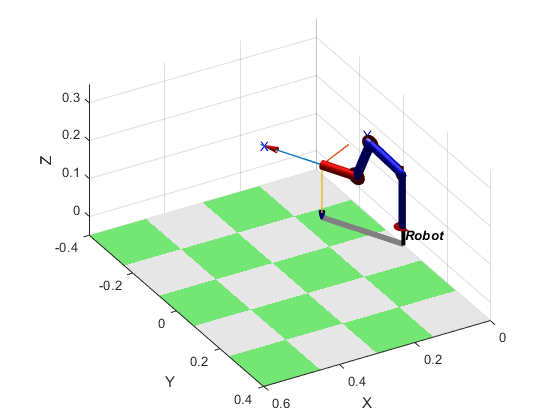

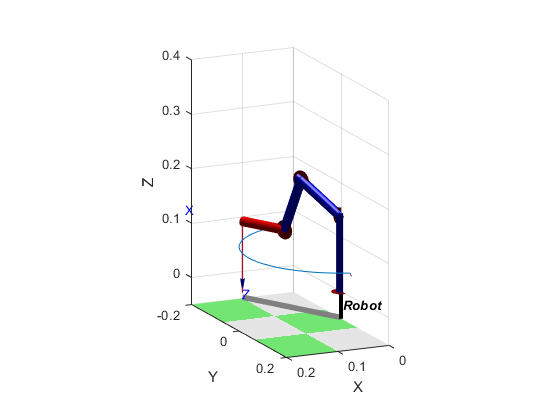

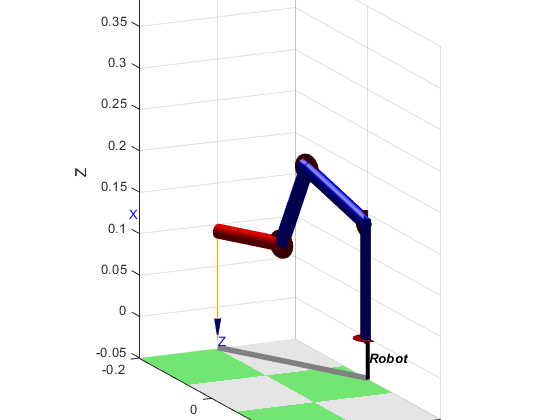

Robot_1.animate(qHabajo)

## Dibujos

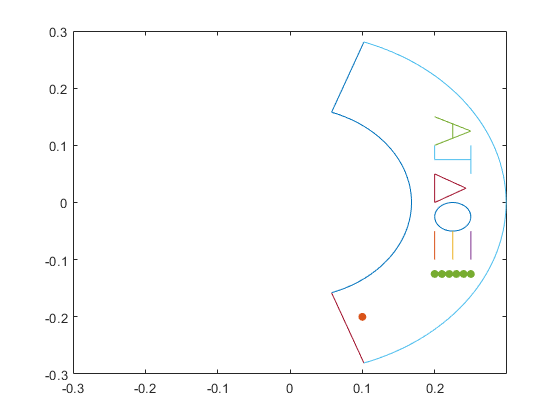



PuntosA=[0.200 0.150;0.250 0.125;0.200 0.100;0.225 0.1125;0.225 0.1375];
PuntosJ=[250 100;250 50;250 75;200 75;200 100]*0.001;
PuntosTri=[200,0;200 50;243.3 25;200,0]*0.001;
Rads=linspace(0,2*pi,50);
PuntosCirc=[225+25*sin(Rads);-25+25*cos(Rads)]'*0.001;
PuntosR1=[200 -50;200 -100]*0.001;
PuntosR2=[225 -50;225 -100]*0.001;
PuntosR3=[250 -50;250 -100]*0.001;
PuntosEQ=[200 -125;210 -125;220 -125;230 -125;240 -125;250 -125]*0.001;


figure()
plot(LimMin(:,1),LimMin(:,2))
hold on
plot(LimMax(:,1),LimMax(:,2))
plot([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)])
plot([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)])
plot(PuntosA(:,1),PuntosA(:,2))
hold on
plot(PuntosJ(:,1),PuntosJ(:,2))
plot(PuntosTri(:,1),PuntosTri(:,2))
plot(PuntosCirc(:,1),PuntosCirc(:,2))
plot(PuntosR1(:,1),PuntosR1(:,2))
plot(PuntosR2(:,1),PuntosR2(:,2))
plot(PuntosR3(:,1),PuntosR3(:,2))
scatter(PuntosEQ(:,1),PuntosEQ(:,2),"filled")
plot3(LimMax(:,1),LimMax(:,2),LimMax(:,3)-0.01)
plot3([LimMax(1,1) LimMin(1,1)],[LimMax(1,2) LimMin(1,2)],[LimMax(1,3) LimMin(1,3)]-0.01)
plot3([LimMax(end,1) LimMin(end,1)],[LimMax(end,2) LimMin(end,2)],[LimMax(end,3) LimMin(end,3)]-0.01)
%Robot_1.plot(Qmin,'view',[150 30],'workspace',[-0.05 0.3 -0.3 0.3 -0.05 0.4],'joints','jointdiam',0.1);
scatter(0.1,-0.2,"filled")
hold off
xlim([-0.3 0.3])

%Robot_1.animate(qHome)

## Descargar la herramienta



qHarriba=ikine4r(0.100,-0.2,0.095,0,L_1,L_2,L_3,L_4)

qHarriba =    -1.1071   -1.0157   -0.1707    1.1864


Robot_1.fkine(qHarriba)

ans =     0.4472   -0.8944   -0.0000    0.1000
   -0.8944   -0.4472    0.0000   -0.2000
   -0.0000    0.0000   -1.0000    0.0950
         0         0         0    1.0000


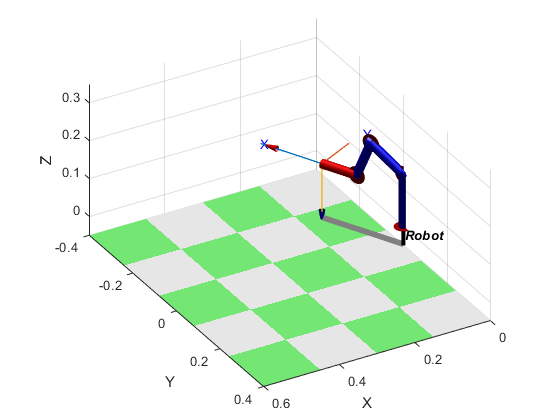

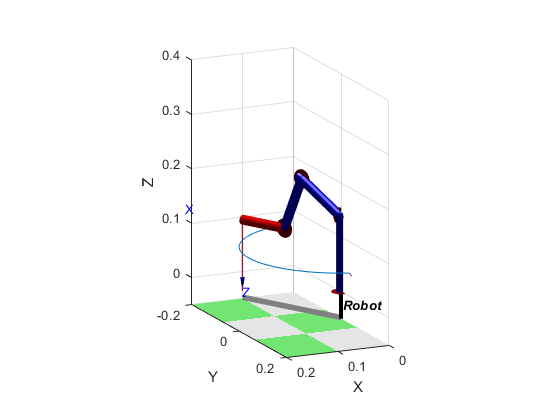

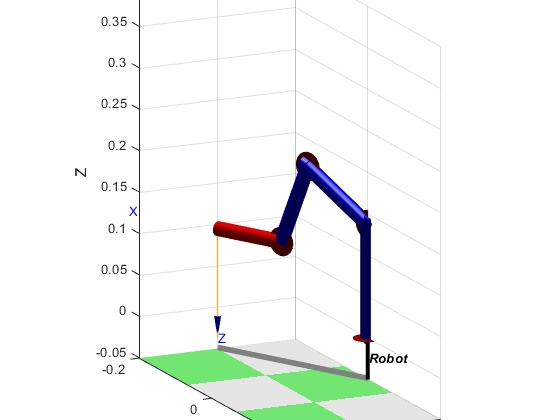

Robot_1.animate(qHarriba)

function T=Ftheta_1(P_x,P_y)
    T=atan2(P_y,P_x);
end

function T=Ftheta_2(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)
    r=sqrt(P_x^2+P_y^2);
    D_r=r-L_4*cos(beta);
    D_z=P_z-L_4*sin(beta)-L_1;
    %T=-2*atan((2*D_z*L_2 + sqrt(- D_r^4 - 2*D_r^2*D_z^2 + 2*D_r^2*L_2^2 + 2*D_r^2*L_3^2 - D_z^4 + 2*D_z^2*L_2^2 + 2*D_z^2*L_3^2 - L_2^4 + 2*L_2^2*L_3^2 - L_3^4))/(D_r^2 + 2*D_r*L_2 + D_z^2 + L_2^2 - L_3^2));
    T=-2*atan((2*D_r*L_2 - sqrt(- D_r^4 - 2*D_r^2*D_z^2 + 2*D_r^2*L_2^2 + 2*D_r^2*L_3^2 - D_z^4 + 2*D_z^2*L_2^2 + 2*D_z^2*L_3^2 - L_2^4 + 2*L_2^2*L_3^2 - L_3^4))/(D_r^2 + D_z^2 + 2*D_z*L_2 + L_2^2 - L_3^2));
end

function T=Ftheta_3(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)
    r=sqrt(P_x^2+P_y^2);
    D_r=r-L_4*cos(beta);
    D_z=P_z-L_4*sin(beta)-L_1;
    %T=2*atan(sqrt((- D_r^2 - D_z^2 + L_2^2 + 2*L_2*L_3 + L_3^2)*(D_r^2 + D_z^2 - L_2^2 + 2*L_2*L_3 - L_3^2))/(D_r^2 + D_z^2 - L_2^2 + 2*L_2*L_3 - L_3^2));
    T=-2*atan((sqrt((- D_r^2 - D_z^2 + L_2^2 + 2*L_2*L_3 + L_3^2)*(D_r^2 + D_z^2 - L_2^2 + 2*L_2*L_3 - L_3^2)) - 2*L_2*L_3)/(D_r^2 + D_z^2 - L_2^2 - L_3^2));
end

function T=Ftheta_4(beta,theta_2,theta_3)
    T=beta-theta_2-theta_3;
end

function T=ikine4r(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4)
    T1=Ftheta_1(P_x,P_y);
    T2=Ftheta_2(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4);
    T3=Ftheta_3(P_x,P_y,P_z,beta,L_1,L_2,L_3,L_4);
    T4=Ftheta_4(beta,T2,T3);
    T=[T1,T2,T3,T4];
end